clear; clc; close all;
% Specifying the filenames of the audio files
transmitter_Audios = ["Short_BBCArabic2.wav", "Short_FM9090.wav", "Short_QuranPalestine.wav", "Short_RussianVoice.wav", "Short_SkyNewsArabia.wav"]; % names of audio files

% Initialize variables used to store sums values or variables that may not store any values in the code.
max_audio_length = 0;
band_widths = cell(1, length(transmitter_Audios));  % Preallocate a cell array to hold the bandwidths' values of the signals.
BW_Of_chosen_Signal = 0;
BW_Of_last_Signal = 0;
current_sum = 0;
max_sum = 0;
FDM_Signal = 0; % Frequency Division Multiplexing
RF_width = 0;
RF_Filter = 0;
%--------------------------------------
IF = 25000; % % If frequency 25 KHz

% Obtaining maximum length
for i = 1:length(transmitter_Audios) % i = 1:5
    % Read the audio file and obtain the audio data
    audio_signal = audioread(transmitter_Audios{i});
    
    % Calculate the length of the audio file (total number of samples)
    audio_length = size(audio_signal, 1); % '1' refers to one channel( one column )
    
    % Check if this audio file has the maximum length so far
    if audio_length > max_audio_length
        max_audio_length = audio_length;
    end
end

% Padding and convert Audios to Mono.
for i = 1:length(transmitter_Audios)
    % Read the audio file and obtain the audio data
    [audio_signal, Fs] = audioread(transmitter_Audios{i}); % getting audio data and sampling frequency
    audio_signal = sum(audio_signal, 2) / size(audio_signal, 2); % [2]Convert from stereo to mono ( The sum function adds the two channels & The size function determines the number of channels)

    % Padding short signals 
    audio_signal(end + max_audio_length - length(audio_signal)) = 0; % [3]short channels will be padded with zeros at the last remaining samples of its length after subtracting from maximum length
    
    audiowrite(transmitter_Audios{i}, audio_signal, Fs); % save the padded monoized audio signals 
end

% FFT Of Desired Audio At The Beginning
fprintf("Choose one of these channels:\n1. Short_BBCArabic2\n2. Short_FM9090\n3. Short_QuranPalestine\n4. Short_RussianVoice\n5. Short_SkyNewsArabia\n");

Choose one of these channels:
1. Short_BBCArabic2
2. Short_FM9090
3. Short_QuranPalestine
4. Short_RussianVoice
5. Short_SkyNewsArabia


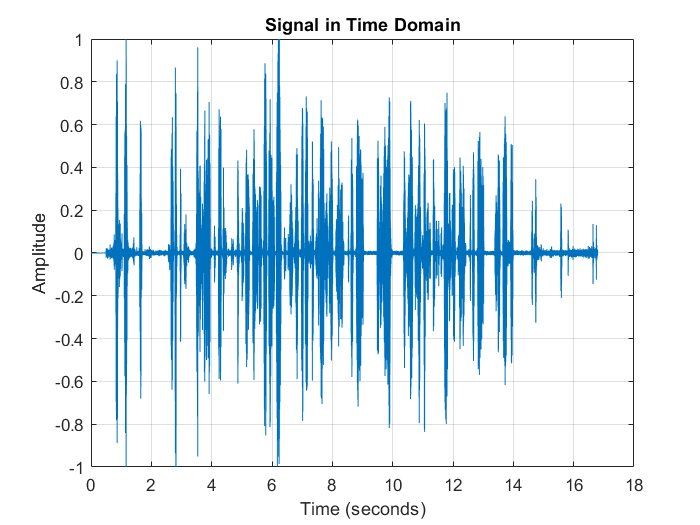

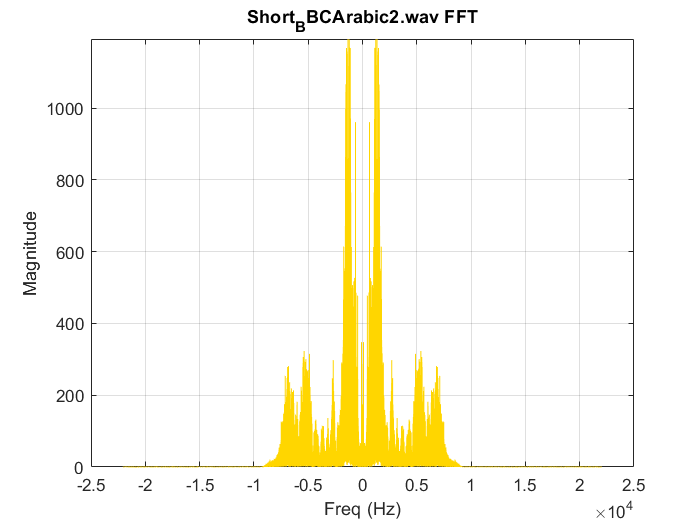

sampling frequency for all audios = 44100 Hz



choose_channel = input("Choose channel: "); 

for i = 1:length(transmitter_Audios)
    [audio_signal, Fs] = audioread(transmitter_Audios(i)); % Read audio and get sampling frequency
    
    if i == choose_channel
        
        nSamples = length(audio_signal);    % Number of samples in the signal
        t = (0:nSamples-1) / Fs;             % Time vector (in seconds)

        % Plot the signal in the time domain 
        plot(t, audio_signal);
        xlabel('Time (seconds)');
        ylabel('Amplitude');
        title('Signal in Time Domain');
        ylim([-max(abs(audio_signal)) max(abs(audio_signal))])
        grid on;
        figure;
        
        AUDIO_SIGNAL = fftshift(fft(audio_signal, length(audio_signal))); % fftshift to be symmetric around 0 (this way give mathmatical meaning)
        Frequency_vector = (-length(AUDIO_SIGNAL)/2 : length(AUDIO_SIGNAL)/2 - 1)'; % adjust frequency axis (we converted it from row to column by (') because we next will divide it by the AUDIO_SIGNAL array which is a column array and dividing amd multiplying must be in same type)
    
        F = Frequency_vector*Fs/length(AUDIO_SIGNAL); % [4]Freq axis
        % freq limits [-Fs/2 ---> Fs/2]  exceeding this range will lead higher frequencies to fold back 

        plot(F, abs(AUDIO_SIGNAL), 'Color', [1, 0.84, 0]) % [5] plotting FFT
        title(transmitter_Audios(choose_channel) + " FFT")
        xlabel("Freq (Hz)")
        ylabel("Magnitude")
        ylim([0 max(abs(AUDIO_SIGNAL))])
        grid on;
        
        disp("sampling frequency for all audios = " + Fs + " Hz"); % [1] display sampling freq
    
        %Fs = 44.1 khz
    end
end

for i = 1:length(transmitter_Audios)
    [audio_signal, Fs] = audioread(transmitter_Audios(i)); % Read audio and get sampling frequency
    
    AUDIO_SIGNAL = fftshift(fft(audio_signal, length(audio_signal))); % fftshift to be symmetric around 0 (this way give mathmatical meaning)
    Frequency_vector = (-length(AUDIO_SIGNAL)/2 : length(AUDIO_SIGNAL)/2 - 1)'; % adjust frequency axis (we converted it from row to column by (') because we next will divide it by the AUDIO_SIGNAL array which is a column array and dividing amd multiplying must be in same type)
    
    F = Frequency_vector*Fs/length(AUDIO_SIGNAL);
    
    % Obtaining BandWidths
    N = length(AUDIO_SIGNAL);
    [pks, freqs] = findpeaks(abs(AUDIO_SIGNAL(1:N/2)), F(1:N/2), 'MinPeakHeight', 0.001*max(abs(AUDIO_SIGNAL(1:N/2)))); % save frequencies and corresponding peaks which achieve the threshold(0.001*max) in two different arrays

    % Compute bandwidth
    full_bandwidth = max(freqs) - min(freqs);
    effective_bandwidth = obw(audio_signal, Fs);
    bandwidth = effective_bandwidth;
    
    disp("full_bandwidth of " + transmitter_Audios(i) + " = " + full_bandwidth + " Hz");  %[6] BW
    disp("effective bandwidth of " + transmitter_Audios(i) + " = " + effective_bandwidth + " Hz");
    
    band_widths{i} = bandwidth;

    if i == choose_channel
        BW_Of_chosen_Signal = bandwidth;
    end
    if i == length(transmitter_Audios)
        BW_Of_last_Signal = bandwidth;
    end
end

full_bandwidth of Short_BBCArabic2.wav = 9212.3327 Hz


effective bandwidth of Short_BBCArabic2.wav = 6826.5246 Hz


full_bandwidth of Short_FM9090.wav = 22049.5831 Hz


effective bandwidth of Short_FM9090.wav = 6423.273 Hz


full_bandwidth of Short_QuranPalestine.wav = 22049.7022 Hz


effective bandwidth of Short_QuranPalestine.wav = 6824.0287 Hz


full_bandwidth of Short_RussianVoice.wav = 22049.6427 Hz


effective bandwidth of Short_RussianVoice.wav = 18276.3907 Hz


full_bandwidth of Short_SkyNewsArabia.wav = 9109.2502 Hz


effective bandwidth of Short_SkyNewsArabia.wav = 7108.9006 Hz


% Calculating the available frequency range between our chosen signal and the signal just before it, as well as the signal just after it (consecutive signals)
for i = choose_channel-1:choose_channel
    if choose_channel == 1
        max_sum = band_widths{choose_channel} + band_widths{choose_channel+1};
    elseif choose_channel == 5
        max_sum = band_widths{choose_channel} + band_widths{choose_channel-1};
    else
        current_sum = band_widths{i} + band_widths{i+1};
        if current_sum > max_sum
            max_sum = current_sum;
        end
    end
end
k0 = BW_Of_chosen_Signal + (50000 - max_sum); % the maximum available frequency range for RF filter to use before including another signal.

k1 = IF; % The maximum available frequency range for the IF filter to use before exceeding 0 Hz

% Modulating
[audio_signal, Fs] = audioread(transmitter_Audios(choose_channel));
fo = 100000; 
n = (choose_channel-1);
delta_f = 50000;                                    
fn_chosen = fo + n*delta_f;

%----------->>>>>----------- Hand Calculations for Violation_1( better to be automated ) -----------<<<<<-----------%

% Fmax1 >> highest freq we reach in whole code in case of ( Violation_1 > Violation_2 ), it appears after FDM Signal Generated = fn(of last signal) + k0.

% Fs/2 should be bigger than Fmax1 to avoid violating Nyquist criteria so we need to increase sampling frequency by multipling Fs by a factor x (Violation_1) to avoid this.

% new FS = x*(Fs/2) > ( Fmax1 + 1000 ) %% 1000 as a safe factor

% x(violation_1) > (2/Fs)*( fmax1 + 1000)

% ex : x > 15.24 --> x = 16

%----------->>>>>----------- Hand Calculations for Violation_2( better to be automated ) -----------<<<<<-----------%

% Fmax2 >> highest freq we reach in whole code in case of ( Violation_2 > Violation_1 ), it appears after the second modulation process of mixer = 2*fn(of chosen_signal) + IF + BW_Of_chosen_Signal

% Fs/2 should be bigger than Fmax2 to avoid violating Nyquist criteria so we need to increase sampling frequency by multipling Fs by a factor x (Violation_2) to avoid this

% x*(Fs/2) > Fmax2

% x(violation_2) > (2/Fs)*(fmax2)

% ex : x > 18.24 --> x = 19

%----------->>>>>----------- Hand Calculations for Violation_3( better to be automated ) -----------<<<<<-----------%

% better to ignore Violation_3 and use directly  Violation_1 if Violation_1 > Violation_2 or Violation_2 if Violation_2 > Violation_1.

% Folding frequencies happens when we reach frequency exceeds Fs/2 and frequencies above that will fold back to lower frequencies.

% aliasing happens when folded back frequencies start to interfernce with our signal which is centered at IF(25k hz) ( after mixer ) so we need to increase sampling frequency by multipling Fs by a factor x (Violation_3) to avoid this aliasing.

% F(aliasing) = sampling Freq - Fmax2 = (x*Fs) - Fmax2 "should be bigger than IF + k1 + 1000" ( This equation was concluded from the above data )

% x*Fs - Fmax2 > IF + k1 + 1000 %% 1000 as a safe factor

% x(Violation_3) > (1/Fs)*( fmax2 + IF + k1 + 1000)

% ex : x > 16.24 --> x = 17

%-------------Automated----------------------------
fmax1 = fo + ( length(transmitter_Audios) - 1 ) * delta_f + k0;
fmax2 = 2*fn_chosen + IF + BW_Of_chosen_Signal;

violation_1 = (2/Fs)*( fmax1 + 1000);   % minimum factor to avoid violation of Nyquist criteria which appears after generarting FDM signal.
violation_2 = (2/Fs)*(fmax2);           % minimum factor to avoid violation of Nyquist criteria which appears after second modulation from Mixer.
violation_3 = (1/Fs)*( fmax2 + IF + k1 + 1000); % minimum factor to avoid aliasing which appears after ignoring the second violation of Nyquist criteria.
                                        % k0 & k1 are added to the main equations to include the RF and IF filter bandwidths.
                                        % 1000 as a safe factor
if violation_1 >= violation_2
    x = violation_1;                                                                                       
elseif violation_1 >= violation_3
    x = violation_1; % it is better that if violation_2 > violation_1 is to make (x = violation_2) directly without further conditions to not violate Nyquist criteria at all but to not increase filter order and not to make process slow, we use lower suitable factor.
else
    x = violation_3;
end
x = ceil(x);  % Round x up to the nearest greater integer
disp("violation_1 = " + num2str(violation_1));

violation_1 = 15.6271


disp("violation_2 = " + num2str(violation_2));

violation_2 = 10.5137


disp("violation_3 = " + num2str(violation_3));

violation_3 = 6.4133


disp("x = " + num2str(x));

x = 16


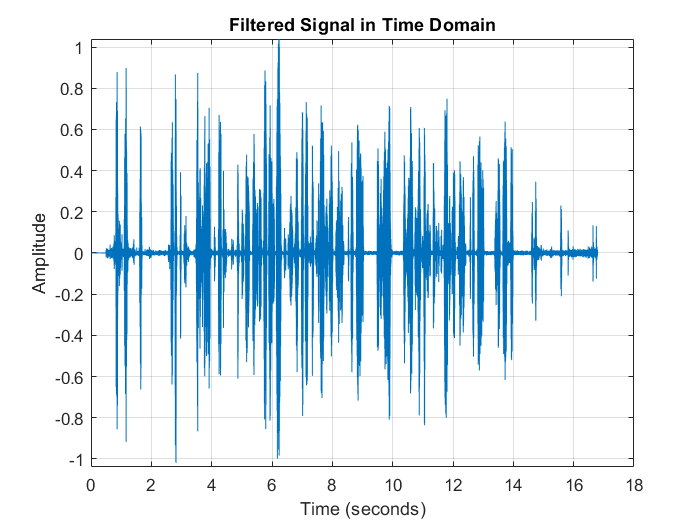

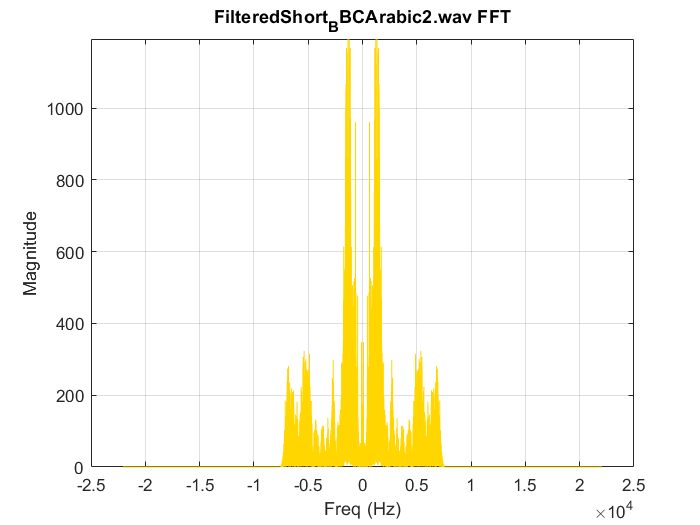

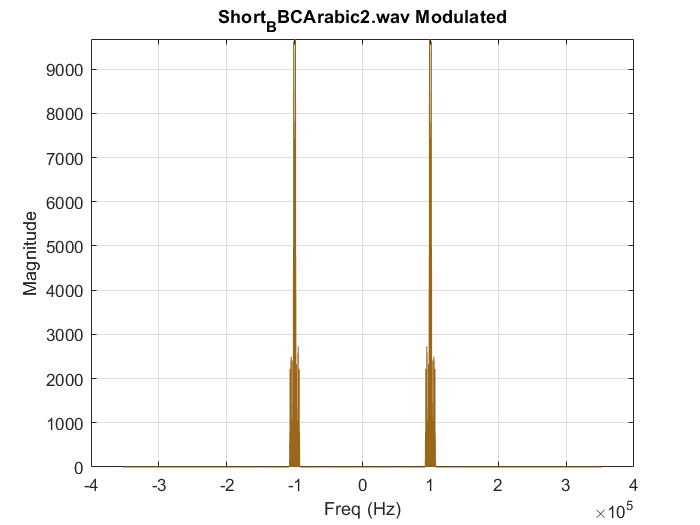

bandwidth of Short_BBCArabic2.wav Modulated = 13653.0492 Hz



% FDM Signal Generation
for i = 1:length(transmitter_Audios)
    % Read the audio file and obtain the audio data
    [audio_signal, Fs] = audioread(transmitter_Audios(i)); % Read audio and get sampling frequency
    % Low pass filter to remove high frequency noisy componet ( keep only 99% of our input signal power).
    F_pass = band_widths{i};           % Edge of the passband - effective Bandwidth -
    F_stop = F_pass + 1000;            % Edge of the stopband
    A_stop = 60;                       % Attenuation in stopband
    A_pass = 1;                        % Amount of ripple allowed in the passband

    Low_Pass_Filter = fdesign.lowpass(F_pass, F_stop, A_pass, A_stop, Fs);
    Low_Pass_Filter = design(Low_Pass_Filter, 'kaiserwin');
    [b, a] = tf(Low_Pass_Filter);
    
    audio_signal = filtfilt(b, a, audio_signal);
    
    if i == choose_channel
        
        nSamples = length(audio_signal);    % Number of samples in the signal
        t = (0:nSamples-1) / Fs;             % Time vector (in seconds)

        % Plot the Filtered signal in the time domain 
        plot(t, audio_signal);
        xlabel('Time (seconds)');
        ylabel('Amplitude');
        title('Filtered Signal in Time Domain');
        ylim([-max(abs(audio_signal)) max(abs(audio_signal))])
        grid on;
        figure;
        
        AUDIO_SIGNAL = fftshift(fft(audio_signal, length(audio_signal))); % fftshift to be symmetric around 0 (this way give mathmatical meaning)
        Frequency_vector = (-length(AUDIO_SIGNAL)/2 : length(AUDIO_SIGNAL)/2 - 1)'; % adjust frequency axis (we converted it from row to column by (') because we next will divide it by the AUDIO_SIGNAL array which is a column array and dividing amd multiplying must be in same type)
    
        F = Frequency_vector*Fs/length(AUDIO_SIGNAL); % [4]Freq axis
        % freq limits [-Fs/2 ---> Fs/2]  exceeding this range will lead higher frequencies to fold back 

        plot(F, abs(AUDIO_SIGNAL), 'Color', [1, 0.84, 0]) % [5] plotting FFT
        title("Filtered" +transmitter_Audios(choose_channel) + " FFT")
        xlabel("Freq (Hz)")
        ylabel("Magnitude")
        ylim([0 max(abs(AUDIO_SIGNAL))])
        grid on;
        figure;
    end
    audio_signal = interp(audio_signal, x); %[8] Fs(new)= x*Fs & length(new) = x*length & magnitude(new) = x*magnitude
    
    fo = 100000;
    n = (i-1);
    delta_f = 50000;
    fn = fo + n*delta_f;
                 
    audio_length = (1:1:length(audio_signal))'; % adjusted to be the same length as our signal
    carrier_signal = cos(2*pi*fn*audio_length*(1/(x*Fs))); % [7] carrier signal cos(𝜔𝑛𝑛𝑇𝑆)
   
    modulated_signal = carrier_signal.*audio_signal; % we use (.*) when multiplying arrays
    MODULATED_SIGNAL = fftshift(fft(modulated_signal));
    Frequency_vector = (-length(MODULATED_SIGNAL)/2:1:length(MODULATED_SIGNAL)/2-1)';

    if i == choose_channel

        plot(Frequency_vector*(x*Fs)/length(MODULATED_SIGNAL), abs(MODULATED_SIGNAL), 'Color', [0.6, 0.4, 0.1])    
        title(transmitter_Audios(choose_channel) + " Modulated")
        xlabel("Freq (Hz)")
        ylabel("Magnitude")
        ylim([0 max(abs(MODULATED_SIGNAL))])
        grid on;
        figure;
    
        bandwidth2 = 2 * BW_Of_chosen_Signal;
        disp("bandwidth of " + transmitter_Audios(choose_channel) + " Modulated = " + bandwidth2 + " Hz");
    end
    FDM_Signal = FDM_Signal + modulated_signal; % summing point 
end

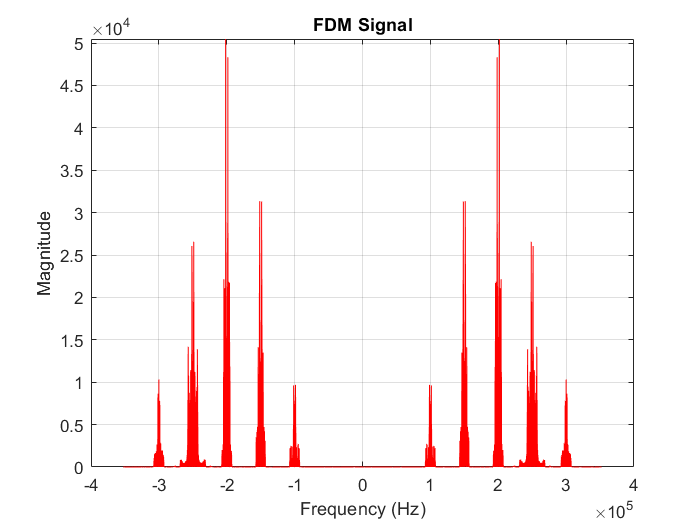

FDM_SIGNAL = fftshift(fft(FDM_Signal));
Frequency_vector = (-length(FDM_SIGNAL)/2:length(FDM_SIGNAL)/2-1)';
plot(Frequency_vector*(x*Fs)/length(FDM_SIGNAL), abs(FDM_SIGNAL), 'r')
title("FDM Signal")
xlabel("Frequency (Hz)")
ylabel("Magnitude")
ylim([0 max(abs(FDM_SIGNAL))])
grid on;


% The RF stage
fprintf("Choose:\n0. Normal operation\n1. Remove RF Filter\n2. 0.1kHz Offset\n3. 1kHz Offset\n");

Choose:
0. Normal operation
1. Remove RF Filter
2. 0.1kHz Offset
3. 1kHz Offset



test = input("0. Normal operation\n1. Remove RF Filter\n2. 0.1kHz Offset\n3. 1kHz Offset\n Choose test : ");

    k_RF = k0 - 100; % 100 as a safe factor
    disp("k_RF = " + num2str(k_RF) + " Hz");

k_RF = 43476.727 Hz


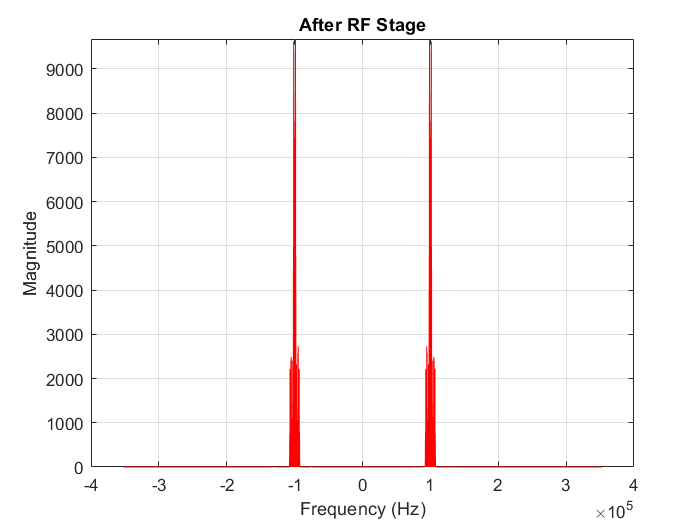


if test ~= 1
    A_stop1 = 60; % Attenuation in the first stopband = 60 dB
    F_pass1 = fn_chosen - 0.5*(k_RF + BW_Of_chosen_Signal);     % Edge of the first  passband, just suitable equation to make sure that we will not exceed our limits under any condition.
    F_pass2 = fn_chosen + 0.5*(k_RF + BW_Of_chosen_Signal);     % Edge of the second passband 
    F_stop1 = fn_chosen - k_RF;                  % Edge of the first  stopband = (fn-k_RF) 
    F_stop2 = fn_chosen + k_RF;                  % Edge of the second stopband = (fn+k_RF) making it symmetric is better
    A_stop2 = 60;                           % Attenuation in the second stopband = 60 dB
    A_pass = 1;   % Amount of ripple allowed in the passband

    RF_Filter = fdesign.bandpass(F_stop1, F_pass1, F_pass2, F_stop2, A_stop1, A_pass, A_stop2, (x*Fs));
    RF_Filter = design(RF_Filter, 'kaiserwin'); % kaiserwin is good as it adjusts the attenuation or ripple depending on your filter parameters. 
    [b, a] = tf(RF_Filter); % this extracts the coefficients of the transfer function of our filter for filtfilt method.
    RF_Signal = filtfilt(b, a, FDM_Signal); % filtfilt is a filtering method that reomve phase destortion.
    %RF_Signal = filter(RF_Filter, FDM_Signal); % may be filter method is more practical for RF filter as it has much less precision due to working at very high frequencies.
    
    RF_SIGNAL  = fftshift(fft(RF_Signal));
    Frequency_vector = (-length(RF_SIGNAL)/2:1:length(RF_SIGNAL)/2-1)';

    plot(Frequency_vector*(x*Fs)/length(RF_SIGNAL), abs(RF_SIGNAL), 'r')
    title("After RF Stage")
    xlabel("Frequency (Hz)")
    ylabel("Magnitude")
    ylim([0 max(abs(RF_SIGNAL))])
    grid on;
end

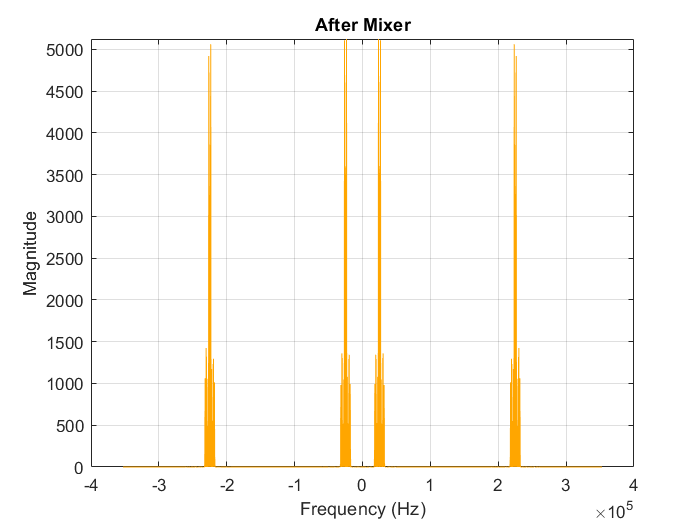


% Mixer (Oscillator 𝜔𝐶 + 𝜔𝐼f)
fn = (choose_channel-1)*50000+100000; % [100, 150, 200, 250, 300] KHz
fLo = fn + IF; % Local oscillator carrier frequency

if test == 1
    RF_Signal = FDM_Signal;  
elseif test == 2
    fLo = fLo + 100; % 0.1k offset
elseif test == 3
    fLo = fLo + 1000; % 1k offset
end       

audio_length = (1:1:length(RF_Signal))';
carrier_signal = cos(2*pi*fLo*audio_length*(1/(x*Fs)));

Mixer_Output_Signal = RF_Signal.*carrier_signal;
MIXER_OUTPUT_SIGNAL = fftshift(fft(Mixer_Output_Signal));
Frequency_vector = (-length(MIXER_OUTPUT_SIGNAL)/2:1:length(MIXER_OUTPUT_SIGNAL)/2-1)';

plot(Frequency_vector*(x*Fs)/length(MIXER_OUTPUT_SIGNAL), abs(MIXER_OUTPUT_SIGNAL), 'Color', [1, 0.65, 0])
title(" After Mixer ")
xlabel("Frequency (Hz)")
ylabel("Magnitude")
ylim([0 max(abs(MIXER_OUTPUT_SIGNAL))])
grid on;


% IF stage

k_IF = k1 - 100; % 100 as a safe factor
disp("k_IF = " + num2str(k_IF) + " Hz");

k_IF = 24900 Hz


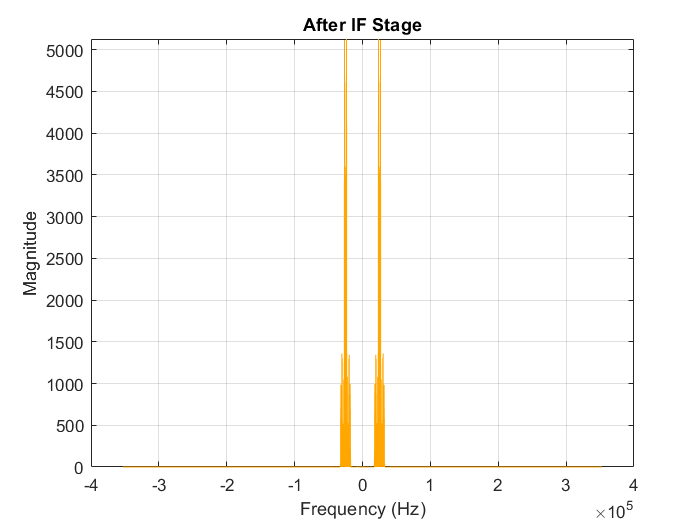


A_stop1 = 60;                             % Attenuation in the first stopband = 60 dB
F_pass1 = IF - 0.5*(k_IF + BW_Of_chosen_Signal);      % Edge of the first  passband
F_pass2 = IF + 0.5*(k_IF + BW_Of_chosen_Signal);      % Edge of the second passband
F_stop1 = IF - k_IF;                 % Edge of the first  stopband = (IF-k_IF)
F_stop2 = IF + k_IF;                 % Edge of the second stopband
A_stop2 = 60;                             % Attenuation in the second stopband = 60 dB
A_pass = 1;                               % Amount of ripple allowed in the passband = 1 dB

IF_Filter = fdesign.bandpass(F_stop1, F_pass1, F_pass2, F_stop2, A_stop1, A_pass, A_stop2, (x*Fs));
IF_Filter = design(IF_Filter, 'kaiserwin');
[b, a] = tf(IF_Filter);
IF_Signal = filtfilt(b, a, Mixer_Output_Signal);
%IF_Signal = 1.5*IF_Signal; % amplification

IF_SIGNAL  = fftshift(fft(IF_Signal));
Frequency_vector = (-length(IF_SIGNAL)/2:1:length(IF_SIGNAL)/2-1)';

plot(Frequency_vector*(x*Fs)/length(IF_SIGNAL), abs(IF_SIGNAL), 'Color', [1, 0.65, 0])
title("After IF Stage")
xlabel("Frequency (Hz)")
ylabel("Magnitude")
ylim([0 max(abs(IF_SIGNAL))])
grid on;

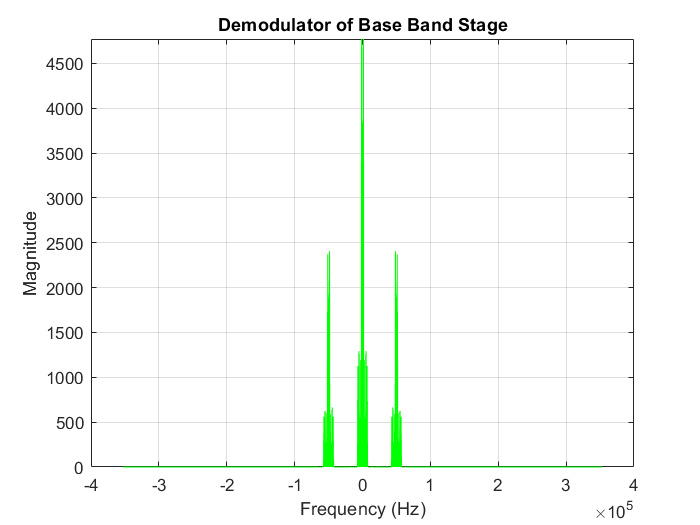


% Base Band Stage (Demodulation)
fc = IF; % BaseBand carrier frequency

audio_length = (1:1:length(IF_Signal))';
carrier_signal = cos(2*pi*fc*audio_length*(1/(x*Fs)));

Base_Band_Signal = IF_Signal.*carrier_signal;
BASE_BAND_SIGNAL = fftshift(fft(Base_Band_Signal));
Frequency_vector = (-length(BASE_BAND_SIGNAL)/2:1:length(BASE_BAND_SIGNAL)/2-1)';

plot(Frequency_vector*(x*Fs)/length(BASE_BAND_SIGNAL), abs(BASE_BAND_SIGNAL), 'g')
title("Demodulator of Base Band Stage")
xlabel("Frequency (Hz)")
ylabel("Magnitude")
ylim([0 max(abs(BASE_BAND_SIGNAL))])
grid on;


% The Base Band detection (LPF)
k2 = 50000 - BW_Of_chosen_Signal; % the largest available frequency range for BaseBand Low Pass filter to use before interacting with its image.
k_BB = k2 - 100; %100 as a safe factor.
disp("k_BB = " + num2str(k_BB) + " Hz");

k_BB = 43073.4754 Hz


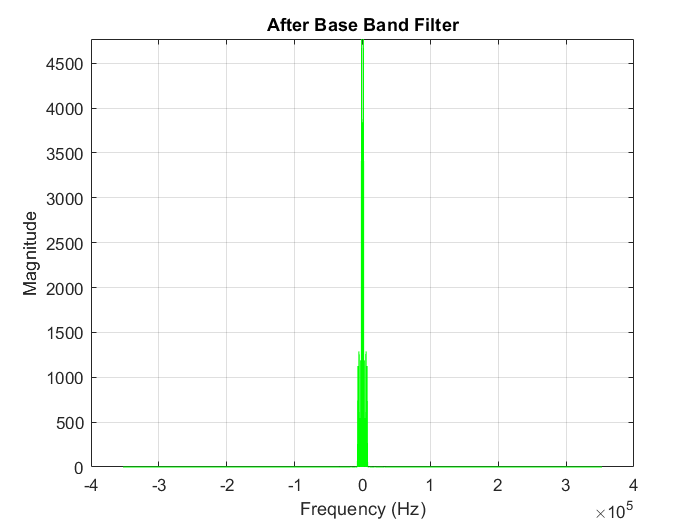


F_pass = 0.5*(k_BB + BW_Of_chosen_Signal); % Edge of the passband
F_stop = k_BB;                             % Edge of the stopband
A_stop = 60;                               % Attenuation in stopband
A_pass = 1;                                % Amount of ripple allowed in the passband

Base_Band_Filter = fdesign.lowpass(F_pass, F_stop, A_pass, A_stop, (x*Fs));
Base_Band_Filter = design(Base_Band_Filter, 'kaiserwin');
[b, a] = tf(Base_Band_Filter);
Base_Band_Signal = filtfilt(b, a, Base_Band_Signal);

BASE_BAND_SIGNAL = fftshift(fft(Base_Band_Signal));
Frequency_vector = (-length(BASE_BAND_SIGNAL)/2:1:length(BASE_BAND_SIGNAL)/2-1)';

plot(Frequency_vector*(x*Fs)/length(BASE_BAND_SIGNAL), abs(BASE_BAND_SIGNAL), 'g')
title("After Base Band Filter")
xlabel("Frequency (Hz)")
ylabel("Magnitude")
ylim([0 max(abs(BASE_BAND_SIGNAL))])
grid on;

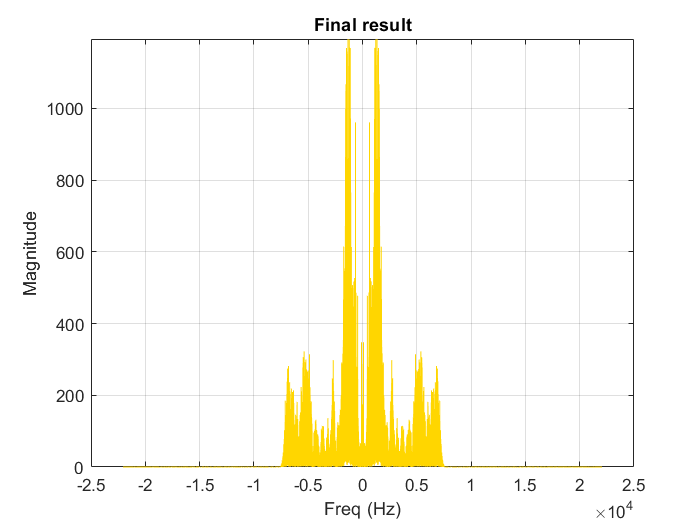


Base_Band_Signal = 4*resample(Base_Band_Signal, 1, x); % resample restores main Fs & length & magnitude by doing the opposite the interp do & multiplied by 4 due to two modulation processses.

BASE_BAND_SIGNAL  = fftshift(fft(Base_Band_Signal));
Frequency_vector = (-length(BASE_BAND_SIGNAL)/2:1:length(BASE_BAND_SIGNAL)/2-1)';

figure
plot((Frequency_vector*Fs/length(BASE_BAND_SIGNAL)), abs(BASE_BAND_SIGNAL), 'Color', [1, 0.84, 0])
title("Final result")
xlabel("Freq (Hz)")
ylabel("Magnitude")
ylim([0 max(abs(BASE_BAND_SIGNAL))])
grid on;

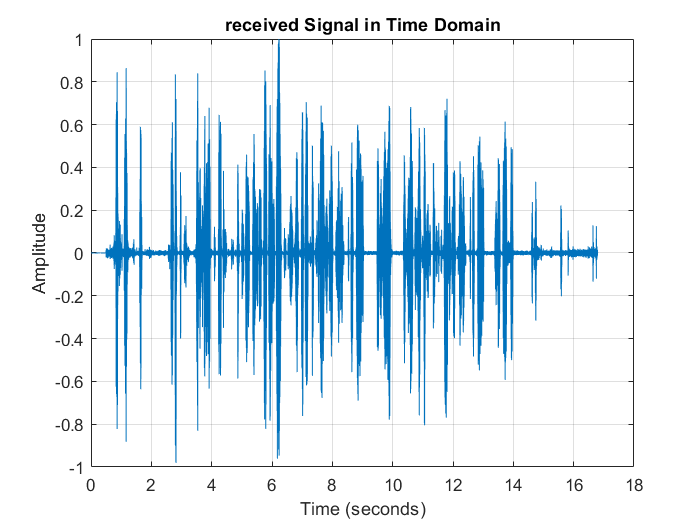

figure

sound(Base_Band_Signal, Fs) % to listen to our station

%Normalize the Base_Band_Signal amplitude before saving
Base_Band_Signal = Base_Band_Signal / max(abs(Base_Band_Signal));  % Normalize to range [-1, 1] because it could potentially has exceeded it during the code

nSamples = length(Base_Band_Signal); % Number of samples in the signal
t = (0:nSamples-1) / Fs;             % Time vector (in seconds)

% Plot the signal in the time domain 
plot(t, Base_Band_Signal);
xlabel('Time (seconds)');
ylabel('Amplitude');
title('received Signal in Time Domain');
ylim([-max(abs(Base_Band_Signal)) max(abs(Base_Band_Signal))])
grid on;


% --------------------saving received signals & different tests-----------------------------
errors = ["Removed_RF for " + transmitter_Audios(choose_channel), "0.1 KHz Offset for " + transmitter_Audios(choose_channel), "1 KHz Offset for "+ transmitter_Audios(choose_channel)]; % three tests
receiver = ["received_BBCArabic2.wav", "received_FM9090.wav", "received_QuranPalestine.wav", "received_RussianVoice.wav", "received_SkyNewsArabia.wav"];

if test == 1 || test == 2 || test == 3
    audiowrite(errors{test}, Base_Band_Signal, Fs); % save test audios, Test{1} Test{2} Test{3}
else
    audiowrite(receiver{choose_channel}, Base_Band_Signal, Fs);
end